## Set up Testing Parameters:

example.neuron_index = 2:5;
example.spike_times = active_processing.spikes.time(example.neuron_index);
example.time_range = [5801 5900];
 
% Restrict the spike train down to a subset of the spikes it fires within the time_range:
% example.restricted_spike_times = Restrict(example.spike_times, [example.time_range(1), example.time_range(2)]); % get spike times
example.fn_perform_restrict_all = @(spikeTimes) Restrict(spikeTimes, [example.time_range(1), example.time_range(2)]);
example.restricted_spike_times = cellfun(example.fn_perform_restrict_all, example.spike_times, 'UniformOutput',false);

% plot([example.restricted_spike_times example.restricted_spike_times],[-1 -0.5],'Color',[0 0 0]); % note, plots all spikes in one command

## Spike density function (SDF, binless firing rate)

binsize = 0.001; % in seconds, so everything else should be seconds too
% [tbin_centers, gau_sdf] = fnSpikeFiringDensity(example, binsize);
[gau_sdf, spk_count, tbin_edges, tbin_centers] = fnSpikeFiringDensity(example.restricted_spike_times, binsize, example.time_range);

Done getting spike count!Performing Convolution...

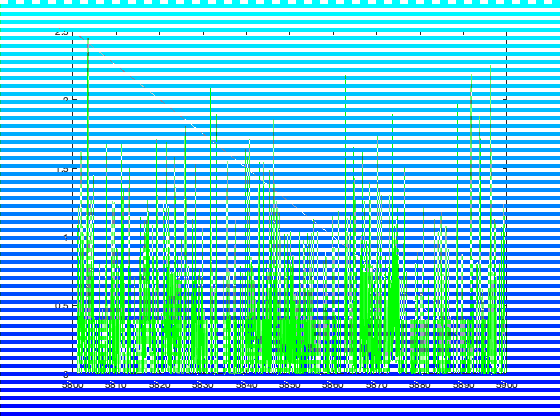

plot(tbin_centers,gau_sdf,'g');

% for i = 1:length(active_processing.spikes.time)
%     
%     [gau_sdf, spk_count, tbin_edges, tbin_centers] = fnSpikeFiringDensity(spike_times, binsize, startEndTimeRange)
% 
% 
% end



## Run Parameters

% Unit Filtering:
filter_config.filter_included_cell_types = {};
% filter_config.filter_included_cell_types = {'pyramidal'};
% filter_config.filter_included_cell_types = {'interneurons'};
filter_config.filter_maximum_included_contamination_level = {2};
[filter_config.filter_active_units, filter_config.original_unit_index] = fnFilterUnitsWithCriteria(active_processing, processing_config.showOnlyAlwaysStableCells, filter_config.filter_included_cell_types, ...
    filter_config.filter_maximum_included_contamination_level);
fprintf('Filter: Including %d of %d total units\n', sum(filter_config.filter_active_units, 'all'), length(filter_config.filter_active_units));

Filter: Including 86 of 126 total units



run.filter_config = filter_config;
run.spike_times = active_processing.spikes.time(filter_config.filter_active_units);
run.time_range = [1 active_processing.behavioral_epochs.end_seconds(end)];
 
% Restrict the spike train down to a subset of the spikes it fires within the time_range:
% example.restricted_spike_times = Restrict(example.spike_times, [example.time_range(1), example.time_range(2)]); % get spike times
run.fn_perform_restrict_all = @(spikeTimes) Restrict(spikeTimes, [run.time_range(1), run.time_range(2)]);
run.restricted_spike_times = cellfun(run.fn_perform_restrict_all, run.spike_times, 'UniformOutput',false);


## Run: Compute SDF

run.binsize = 0.010; % in seconds, so everything else should be seconds too
% [tbin_centers, gau_sdf] = fnSpikeFiringDensity(example, binsize);
[gau_sdf, spk_count, tbin_edges, tbin_centers] = fnSpikeFiringDensity(run.restricted_spike_times, run.binsize, run.time_range);

Done getting spike count!
Performing Convolution...
done!


## Write out results to file:

data_config.output.March24OutputFilepath = '/Users/pho/Dropbox/Classes/Spring 2021/PIBS 600 - Rotations/Rotation_3_Kamran Diba Lab/DataProcessingProject/ResultsTemp/March 24/smoothed.mat';

% temp.smoothedVariablesList = {'gau_sdf', 'tbin_edges', 'tbin_centers', 'spk_count', 'run'};
%% Load from the file:
% load(data_config.output.March24OutputFilepath, 'gau_sdf', 'tbin_edges', 'tbin_centers', 'spk_count', 'run');

if ~exist(data_config.output.March24OutputFilepath, 'file')
    fprintf('writing out to %s...\n', data_config.output.March24OutputFilepath);
    save(data_config.output.March24OutputFilepath, 'gau_sdf', 'tbin_edges', 'tbin_centers', 'spk_count', 'run');
    fprintf('done.\n');
else
    error('File already exists!')
end

writing out to /Users/pho/Dropbox/Classes/Spring 2021/PIBS 600 - Rotations/Rotation_3_Kamran Diba Lab/DataProcessingProject/ResultsTemp/March 24/smoothed.mat...


done.


## Add Bin Size:


%     across_experiment_results{1, 1}.processing_config
curr_bin_sizes = processing_config.step_sizes;
if ismember(binsize, curr_bin_sizes)
    error('bin size already exists!');
else

% active_processing.processed_array{i}] = fnPreProcessSpikeData(active_processing, data_config, num_of_electrodes, timesteps_array{i});
%     processing_config.step_sizes = [processing_config.step_sizes binsize];
%     processing_config.num_step_sizes = length(processing_config.step_sizes);
%     new_step_size_index = processing_config.num_step_sizes;

%     timesteps_array{new_step_size_index} = seconds(active_processing.behavioral_epochs.start_seconds(1):binsize:active_processing.behavioral_epochs.end_seconds(end));
    
%     active_processing.processed_timestamps{new_step_size_index} = [0.1; 0.]
%     active_processing.processed_array{new_step_size_index}.all.binned_spike_counts = spk_count;
%     results_array{new_step_size_index}
    
%     active_expt_index = 1;
%     current_binning_index = 1;
%     
% %     active_binning_resolution = across_experiment_results{active_expt_index}.processing_config.step_sizes{current_binning_index};
%     temp.curr_timestamps = across_experiment_results{active_expt_index}.timesteps_array{new_step_size_index};
%     temp.curr_processed = across_experiment_results{active_expt_index}.active_processing.processed_array{new_step_size_index};
%     active_results = across_experiment_results{active_expt_index}.results_array{new_step_size_index};

end



## Test SDF

example.neuron_index
plot()


if isempty(filter_config.filter_included_cell_types)
    filter_description_string.cells = 'All Cells';
else
    num_cell_types = length(filter_config.filter_included_cell_types);
    filter_description_string.cells = join(filter_config.filter_included_cell_types,'|');
    filter_description_string.cells = [filter_description_string.cells{1} ' Cells'];
    if num_cell_types == 1
        % Append ' Only' to the end of the string if there's only one cell type (like 'Pyramidal Only'
        filter_description_string.cells = [filter_description_string.cells ' Only'];
    end
end

filter_description_string.cells = strcat(filter_description_string.cells)

filter_description_string = struct with fields:
    cells: 'pyramidal Cells Only'


    
[filter_description_string] = fnGenerateFilterDescriptionString(filter_config)

filter_description_string = struct with fields:
    cells: 'pyramidal Only'